11.03

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
Ts = 0.01; % [s]
Pc = tf([mot.k], [mot.T 1 0]);
Pd = c2d(Pc, Ts, "zoh");

alpha = 0.17;
tau = 0.015;

Cs = tf([tau 1], [tau * alpha 1]);
z = tf('z', Ts);
s = (z - 1) / Ts;
CdFE = (1 + tau * s) / (1 + tau * alpha * s);
CdTU = c2d(Cs, Ts, "tustin");

Studio il modello con controllore discretizzato tramite il metodo di Eulero in avanti

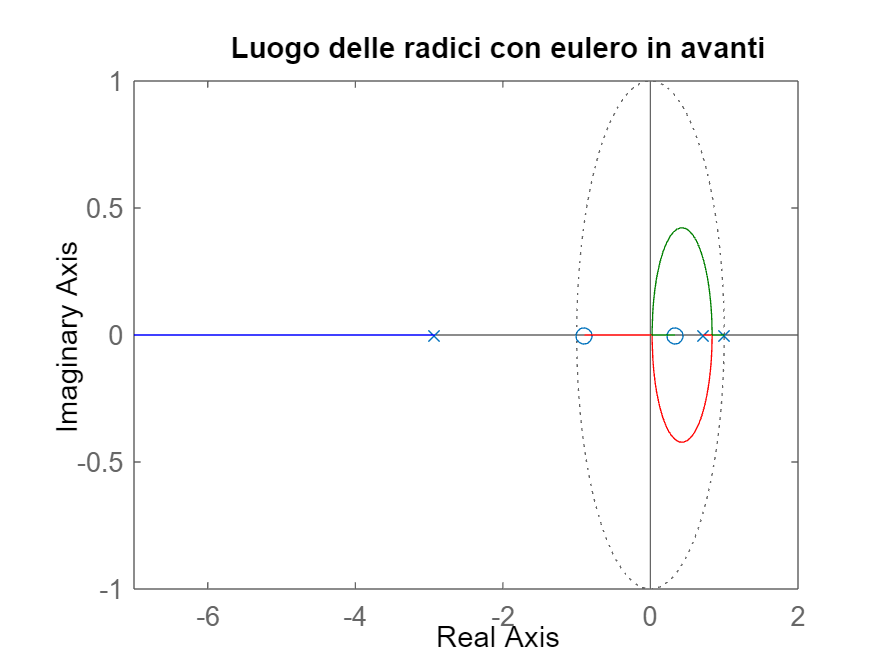

LFE = Pd * CdFE;
close all
figure(1)
rlocus(LFE)
title("Luogo delle radici con Eulero in avanti")

Per ogni valore di k >= 0, il sistema in catena chiusa risulta instabile.

Studio il modello con controllore discretizzato tramite il metodo di Tustin

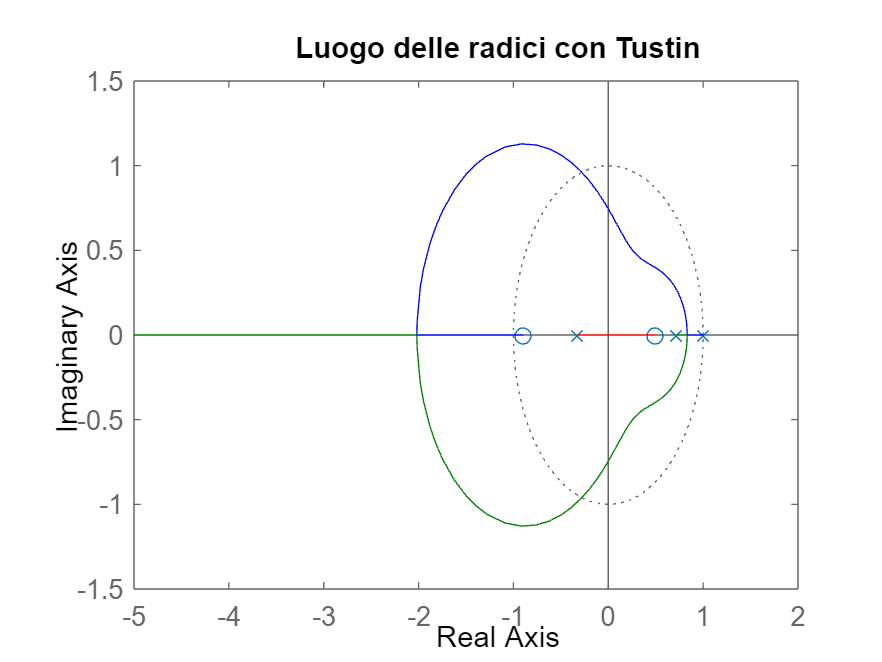

LTU = Pd * CdTU;
close all
figure(2)
rlocus(LTU)
title("Luogo delle radici con Tustin")


kcrit = margin(LTU);

kcrit = 73.1085

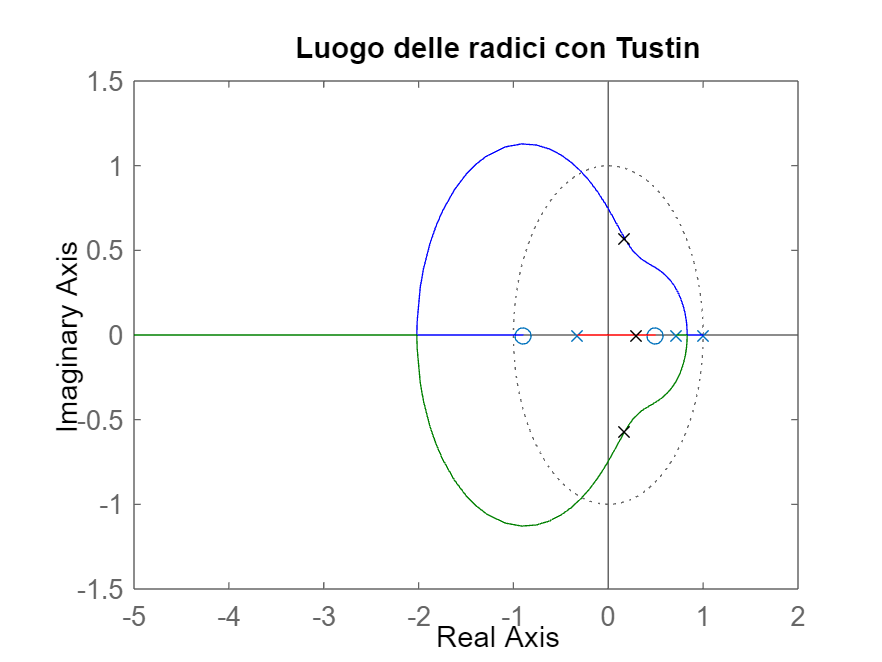

k = kcrit / 2;
TTU = minreal(feedback(k * LTU, 1), 1e-6);
pTU = pole(TTU);

figure(2)
hold on
plot(real(pTU), imag(pTU), "kx")

Tutti e tre i poli si trovano all'interno del cerchio unitario, dunque il sistema è BIBO stabile.

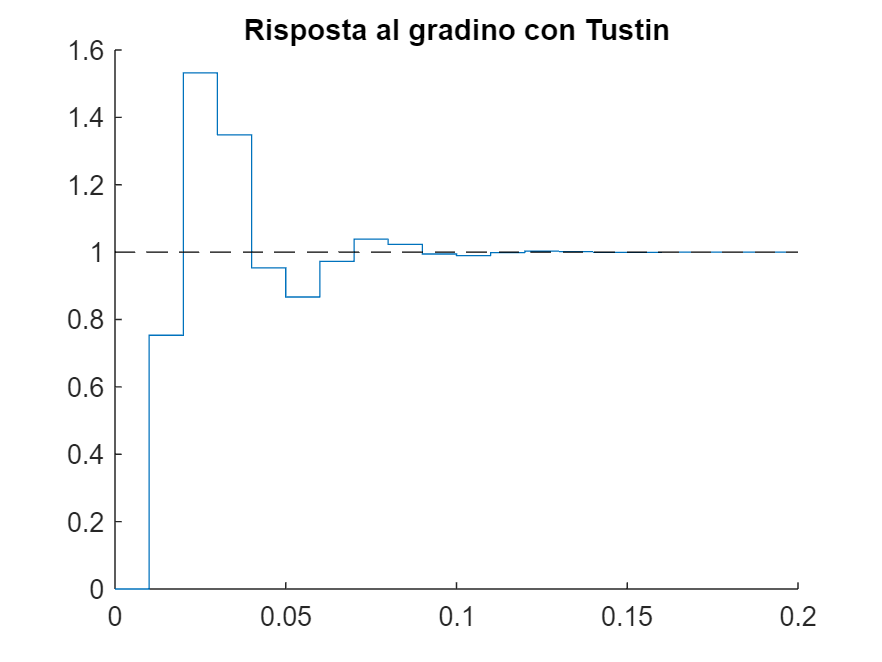

[ys, ts] = step(TTU);
close all
figure(3)
hold on
stairs(ts, ys)
plot([ts(1), ts(end)], [1, 1], 'k--');
title("Risposta al gradino con Tustin")

stepinfo(ys, ts, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.0106
    TransientTime: 0.0579
     SettlingTime: 0.0579
      SettlingMin: 0.8668
      SettlingMax: 1.5319
        Overshoot: 53.1968
       Undershoot: 0
             Peak: 1.5319
         PeakTime: 0.0200


La sovraelongazione percentuale è M = 53.1968%, mentre il tempo di assestamento al 5% è t = 0.0579s.